# SE 424: State-Space Design for Control

## Computational Assignment 1 Solution

Student Name: Ethan Cao

UIN: 670590747

__________________________________________________________________________________________________________

## Flexible Shaft Model: 

### A- True model: System equations and Simulink visualization

Visualize system in Simulink with u=0 and d=0:  

x0=[0.1;0;0;0]; %Initial Condition 
project=openProject("VirtualControlsLaboratory.prj");
sim('SimHw1',20) %First arguemnt is Simulink file name, second argument is time duration for simulation  

ans =   Simulink.SimulationOutput:

             ScopeData1: [120x5 double] 
                   tout: [120x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Define model paramerts: (Please do not change these)

global m l k J1 J2 g b1 b3 mag omega %parameters defined global so they can be used inside all functions 
m = .1; l = 0.5; J1 = 1; J2 = 2; k = 1; g = 9.8; b1 = 1; b3 = 5;

### waB- Simulate true model vs linearized

Here, we will compare the behavior of the true model with the behavior of the linearirzed model near the equilibrium point:

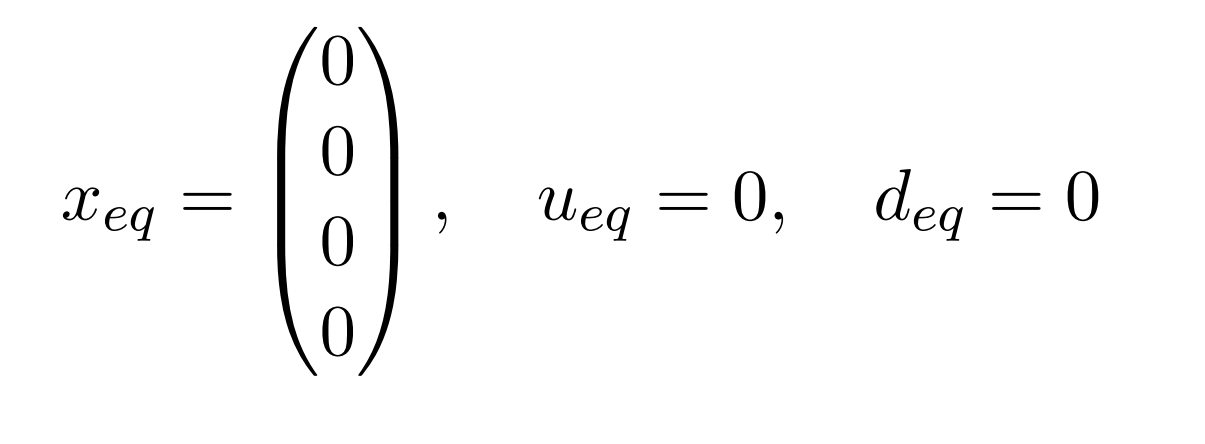

We will simulate the system where the input is a PD controller and the disturbance is a sinousidal. In particular, let 

where 

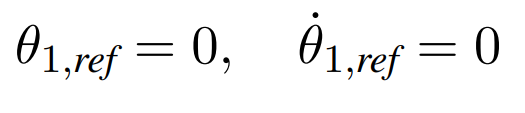

#### Nonlinear flexible shaft model: 

1- Define disturbance function: 

**Task #1: Define d as a sinusoidal function of time with magnitude mag and frequency omega **

function d= disturbance(t)
mag=1;
omega=.4;
%write your code here
d = sin(omega*t) * mag
end

2- Specifiy simulation time and initial condition 

x0=[0;0;0;0]% Initial condition 

x0 =      0
     0
     0
     0


%PD controller parameters
Tfinal=30 %Simulation final time 

Tfinal = 30

Trange=[0,Tfinal] %Simulation period  

Trange =      0    30


3- Define input function:

function u=input(theta1,theta1dot)

    kp=.8; kd=.001;
    theta_ref=[0;0];

    %error from reference 
    error_theta1 = theta_ref(1)-theta1; 
    error_theta1dot = theta_ref(2)-theta1dot;

    u = kp * (error_theta1) + kd *(error_theta1dot) ;
end

4- ODE Simulation Function:

**Task #2: Complete the following function to simulate the nonlinear flexible shaft model: **

function dxdt = flexible_shaft(t,x)

%Here we call the global paramters of the model to be used in the simulation function
global m J1 J2 k g b1 b3 l kp kd 

u = input(x(1),x(3));

 %Implement the nonlinear dynamics with u and d as inputs to your system 
dx1 = x(2);
dx2 = m*g*l/J1 * sin(x(1)) - k*(x(1)-x(3))/J1;
dx3 = x(4);
dx4 = -k/J2*(x(3)-x(1)) - (b1*x(4) + b3*x(4).^3)/J2 + (u+disturbance(t))/J2;
  %Write your code here 
dxdt = [dx1;dx2;dx3;dx4];
end

5- ODE solver:

[t1,flexibleshaft] = ode45(@(t,x)flexible_shaft(t,x), Trange, x0);

d = 0

d = 0.2377

d = 0.3523

d = 0.8192

d = 0.8756

d = 0.9320

d = 0.9320

d = 0.0677

d = 0.1014

d = 0.2676

d = 0.2964

d = 0.3322

d = 0.3322

d = 0.0339

d = 0.0508

d = 0.1350

d = 0.1499

d = 0.1685

d = 0.1685

d = 0.0169

d = 0.0254

d = 0.0677

d = 0.0752

d = 0.0845

d = 0.0845

d = 0.1014

d = 0.1098

d = 0.1518

d = 0.1592

d = 0.1685

d = 0.1685

d = 0.1916

d = 0.2031

d = 0.2602

d = 0.2703

d = 0.2828

d = 0.2828

d = 0.3060

d = 0.3175

d = 0.3742

d = 0.3841

d = 0.3965

d = 0.3965

d = 0.4228

d = 0.4358

d = 0.4995

d = 0.5106

d = 0.5243

d = 0.5243

d = 0.5621

d = 0.5805

d = 0.6683

d = 0.6831

d = 0.7011

d = 0.7011

d = 0.7415

d = 0.7607

d = 0.8469

d = 0.8604

d = 0.8764

d = 0.8764

d = 0.9062

d = 0.9197

d = 0.9716

d = 0.9781

d = 0.9851

d = 0.9851

d = 0.9952

d = 0.9982

d = 0.9920

d = 0.9873

d = 0.9798

d = 0.9798

d = 0.9605

d = 0.9485

d = 0.8661

d = 0.8477

d = 0.8231

d = 0.8231

d = 0.7787

d = 0.7548

d = 0.6208

d = 0.5946

d = 0.5609

d = 0.5609

d = 0.4942

d = 0.4597

d = 0.2776

d = 0.2439

d = 0.2013

d = 0.2013

d = 0.5106

d = 0.4847

d = 0.3494

d = 0.3245

d = 0.2929

d = 0.2929

d = 0.2354

d = 0.2064

d = 0.0587

d = 0.0323

d = -8.6575e-04

d = -8.6575e-04

d = -0.0632

d = -0.0944

d = -0.2479

d = -0.2747

d = -0.3079

d = -0.3079

d = -0.3809

d = -0.4166

d = -0.5846

d = -0.6123

d = -0.6459

d = -0.6459

d = -0.3539

d = -0.3766

d = -0.4864

d = -0.5052

d = -0.5284

d = -0.5284

d = -0.5691

d = -0.5890

d = -0.6829

d = -0.6986

d = -0.7177

d = -0.7177

d = -0.7569

d = -0.7756

d = -0.8588

d = -0.8718

d = -0.8871

d = -0.8871

d = -0.9151

d = -0.9276

d = -0.9756

d = -0.9815

d = -0.9877

d = -0.9877

d = -0.9964

d = -0.9988

d = -0.9914

d = -0.9867

d = -0.9795

d = -0.9795

d = -0.9597

d = -0.9474

d = -0.8624

d = -0.8434

d = -0.8180

d = -0.8180

d = -0.7720

d = -0.7472

d = -0.6082

d = -0.5810

d = -0.5461

d = -0.5461

d = -0.4765

d = -0.4405

d = -0.2508

d = -0.2158

d = -0.1716

d = -0.1716

d = -0.4915

d = -0.4634

d = -0.3163

d = -0.2892

d = -0.2550

d = -0.2550

d = -0.1926

d = -0.1612

d = -0.0019

d = 0.0265

d = 0.0620

d = 0.0620

d = 0.1257

d = 0.1573

d = 0.3125

d = 0.3394

d = 0.3726

d = 0.3726

d = 0.4410

d = 0.4743

d = 0.6300

d = 0.6555

d = 0.6864

d = 0.6864

d = 0.4185

d = 0.4410

d = 0.5494

d = 0.5678

d = 0.5904

d = 0.5904

d = 0.6300

d = 0.6492

d = 0.7388

d = 0.7536

d = 0.7716

d = 0.7716

d = 0.8075

d = 0.8244

d = 0.8982

d = 0.9093

d = 0.9224

d = 0.9224

d = 0.9454

d = 0.9555

d = 0.9906

d = 0.9941

d = 0.9974

d = 0.9974

d = 1.0000

d = 0.9994

d = 0.9772

d = 0.9699

d = 0.9594

d = 0.9594

d = 0.9332

d = 0.9177

d = 0.8179

d = 0.7964

d = 0.7681

d = 0.7681

d = 0.7142

d = 0.6854

d = 0.5261

d = 0.4953

d = 0.4560

d = 0.4560

d = 0.3755

d = 0.3341

d = 0.1189

d = 0.0797

d = 0.0306

d = 0.0306

d = 0.3975

d = 0.3677

d = 0.2132

d = 0.1850

d = 0.1496

d = 0.1496

d = 0.0854

d = 0.0531

d = -0.1083

d = -0.1368

d = -0.1723

d = -0.1723

d = -0.2414

d = -0.2754

d = -0.4399

d = -0.4678

d = -0.5021

d = -0.5021

d = -0.5540

d = -0.5792

d = -0.6966

d = -0.7158

d = -0.7391

d = -0.7391

d = -0.7750

d = -0.7921

d = -0.8682

d = -0.8801

d = -0.8942

d = -0.8942

d = -0.9216

d = -0.9339

d = -0.9798

d = -0.9852

d = -0.9908

d = -0.9908

d = -0.9979

d = -0.9996

d = -0.9887

d = -0.9835

d = -0.9755

d = -0.9755

d = -0.9545

d = -0.9417

d = -0.8548

d = -0.8356

d = -0.8101

d = -0.8101

d = -0.7635

d = -0.7386

d = -0.5988

d = -0.5715

d = -0.5366

d = -0.5366

#### Linear flexible shaft model: 

6- ODE Simulation Function for linear model: 

**Task #3: Complete the following function to simulate the linear flexible shaft model: **


function dxdt2 = flexible_shaft_linear(t,x)
global m J1 J2 k g b1 b3 l kp kd 

 %Implement the linear dynamics with u and d as inputs to your system 

  %Write your code here 
u = input(x(1),x(3));

 %Implement the nonlinear dynamics with u and d as inputs to your system 
dx1 = x(2);
dx2 = (m*g*l-k)/J1 * x(1) + k/J1 * x(3);
dx3 = x(4);
dx4 = -k/J2*(x(3)-x(1)) - (b1*x(4))/J2 + (u+disturbance(t))/J2;
  %Write your code here 
dxdt2 = [dx1;dx2;dx3;dx4];
end

7- ODE solver for linear model:

[t2,flexibleshaftlinear] = ode45(@(t,x)flexible_shaft_linear(t,x), Trange, x0);

d = 0

d = 0.2377

d = 0.3523

d = 0.8192

d = 0.8756

d = 0.9320

d = 0.9320

d = 0.0680

d = 0.1019

d = 0.2688

d = 0.2978

d = 0.3337

d = 0.3337

d = 0.0340

d = 0.0510

d = 0.1357

d = 0.1506

d = 0.1693

d = 0.1693

d = 0.0170

d = 0.0255

d = 0.0680

d = 0.0755

d = 0.0850

d = 0.0850

d = 0.1019

d = 0.1103

d = 0.1525

d = 0.1600

d = 0.1693

d = 0.1693

d = 0.1924

d = 0.2039

d = 0.2610

d = 0.2711

d = 0.2836

d = 0.2836

d = 0.3068

d = 0.3183

d = 0.3750

d = 0.3849

d = 0.3973

d = 0.3973

d = 0.4236

d = 0.4366

d = 0.5003

d = 0.5113

d = 0.5250

d = 0.5250

d = 0.5623

d = 0.5805

d = 0.6670

d = 0.6815

d = 0.6994

d = 0.6994

d = 0.7398

d = 0.7592

d = 0.8457

d = 0.8592

d = 0.8754

d = 0.8754

d = 0.9077

d = 0.9221

d = 0.9762

d = 0.9826

d = 0.9892

d = 0.9892

d = 0.9978

d = 0.9996

d = 0.9849

d = 0.9781

d = 0.9679

d = 0.9679

d = 0.9406

d = 0.9240

d = 0.8123

d = 0.7877

d = 0.7552

d = 0.7552

d = 0.6953

d = 0.6633

d = 0.4860

d = 0.4518

d = 0.4081

d = 0.4081

d = 0.3269

d = 0.2853

d = 0.0708

d = 0.0320

d = -0.0165

d = -0.0165

d = -0.1325

d = -0.1899

d = -0.4634

d = -0.5086

d = -0.5632

d = -0.5632

d = -0.6521

d = -0.6936

d = -0.8658

d = -0.8897

d = -0.9164

d = -0.9164

d = -0.9548

d = -0.9697

d = -0.9996

d = -0.9970

d = -0.9905

d = -0.9905

d = -0.9681

d = -0.9520

d = -0.8255

d = -0.7955

d = -0.7550

d = -0.7550

d = -0.6611

d = -0.6097

d = -0.3168

d = -0.2601

d = -0.1879

d = -0.1879

d = -0.0752

d = -0.0184

d = 0.2628

d = 0.3112

d = 0.3706

d = 0.3706

d = 0.4762

d = 0.5267

d = 0.7489

d = 0.7823

d = 0.8210

d = 0.8210

d = 0.8919

d = 0.9210

d = 0.9985

d = 1.0000

d = 0.9965

d = 0.9965

d = 0.9803

d = 0.9674

d = 0.8564

d = 0.8290

d = 0.7917

d = 0.7917

d = 0.7172

d = 0.6764

d = 0.4426

d = 0.3967

d = 0.3379

d = 0.3379

d = 0.2303

d = 0.1753

d = -0.1043

d = -0.1538

d = -0.2151

d = -0.2151

d = -0.3408

d = -0.4016

d = -0.6747

d = -0.7165

d = -0.7653

d = -0.7653

d = -0.8503

d = -0.8862

d = -0.9929

d = -0.9985

d = -0.9997

d = -0.9997

d = -0.9880

d = -0.9760

d = -0.8560

d = -0.8248

d = -0.7820

d = -0.7820

d = -0.7390

d = -0.7163

d = -0.5913

d = -0.5673

d = -0.5366

d = -0.5366

8- Plot linear vs nonlinear model: 

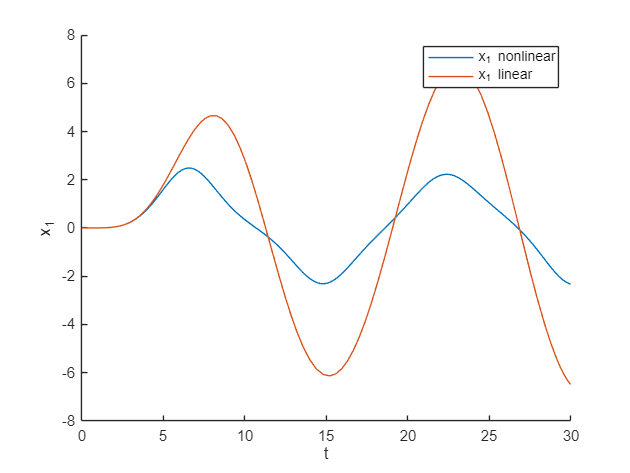

figure(1)
hold on 
plot (t1,flexibleshaft(:,1))
plot (t2,flexibleshaftlinear(:,1))
legend('x_1 nonlinear','x_1 linear')
xlabel('t') 
ylabel('x_1')
hold off 

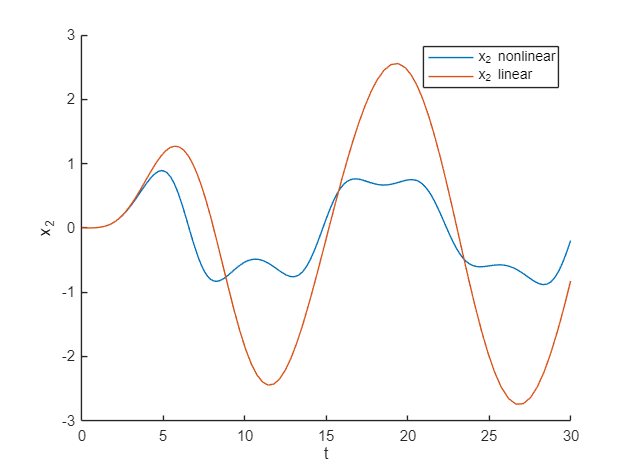

figure(2) 
hold on 
plot (t1,flexibleshaft(:,2))
plot (t2,flexibleshaftlinear(:,2))
legend('x_2 nonlinear','x_2 linear')
xlabel('t') 
ylabel('x_2')
hold off 

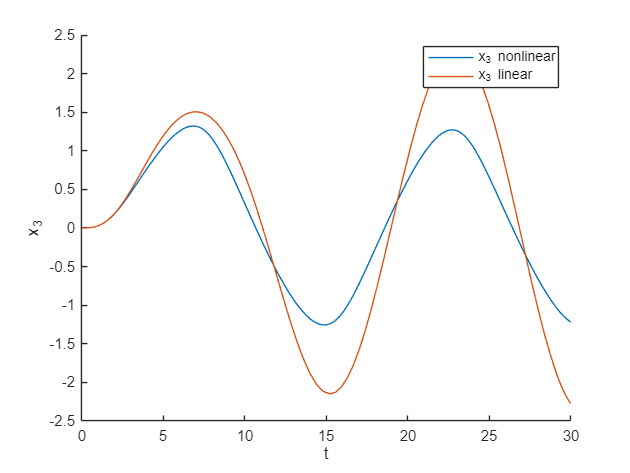

figure(3) 
hold on 
plot (t1,flexibleshaft(:,3))
plot (t2,flexibleshaftlinear(:,3))
legend('x_3 nonlinear','x_3 linear')
xlabel('t') 
ylabel('x_3')
hold off 

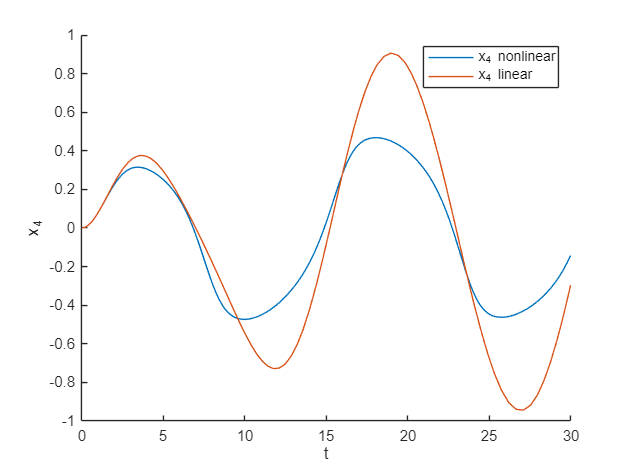

figure(4) 
hold on 
plot (t1,flexibleshaft(:,4))
plot (t2,flexibleshaftlinear(:,4))
legend('x_4 nonlinear','x_4 linear')
xlabel('t') 
ylabel('x_4')
hold off 

9-  ** Task #4: Change the amplitude and the magnitude of the sinousidal funtion within the range of [0.1,1] then rerun the simulation and the plots and notice the change in the plots.**

## Rigid Shaft Model 

Here, will we consider the model obtained after applying the assumption that the shaft is rigid, so both the shaft and motor are considered to move as one body and we only have one angle. We will compare the behavior of the nonlinear rigid model with the behavior of the linearization near the equibruim point: 

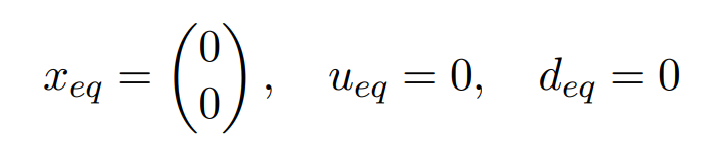

#### Nonlinear rigid model: 

1- Specifiy the simulation time, initial condition and PD control parameters:

x0=[0;0]% Initial condition 

x0 =      0
     0


Tfinal=30; %Simulation final time
Trange=[0,Tfinal] %Simulation period 

Trange =      0    30


2- Simulate the nonlinear model for the same pre-defined disturbance and with the PD controller: 

**Task #5: Complete the following function to simulate the nonlinear rigid shaft model: **


function dxdt = rigid_shaft(t,x)
global m J1 J2 k g b1 b3 l kp kd 

    u = input(x(1),x(2));
    
   %Implement the nonlinear dynamics with u and d as the inputs to your system 

  %Write your code here 

end

3- ODE Solver:

[t1,rigidshaft] = ode45(@(t,x)rigid_shaft(t,x), Trange, x0);

Output argument "dxdt" (and possibly others) not assigned a value in the execution with "Computational1_Cao_E>rigid_shaft" function.

Error in Computational1_Cao_E>@(t,x)rigid_shaft(t,x) (line 107)
[t1,rigidshaft] = ode45(@(t,x)rigid_shaft(t,x), Trange, x0);

Error in odearguments (line 93)
f0 = ode(t0,y0,args{:});

Error in <a hre

#### Linearized rigid shaft model: 

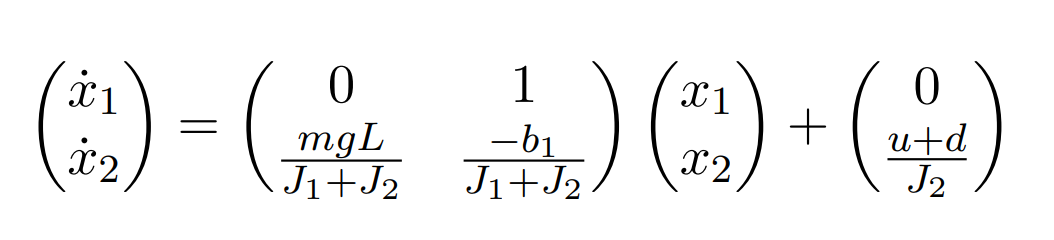

4- ODE simulation function for linear model:

**Task #6: Complete the following function to simulate the linear rigid shaft model: **


function dxdt = rigid_shaft_linear(t,x)
global m J1 J2 k g b1 b3 l kp kd 

 %Implement the linear dynamics with u and d as the inputs to your system 

  %Write your code here 
end

5- ODE Solver: 

[t2,rigidshaftlinear] = ode45(@(t,x)rigid_shaft_linear(t,x), Trange, x0);

6- Plot linear vs nonlinear model: 

**Task #7: Plot the states of the nonlinear rigid shaft model vs the linear rigid shaft model: ** 

%Write your code here 

7- ** Task #8: Change the amplitude and the magnitude of the sinousidal funtion within the range of [0.1,1] then rerun the simulation and the plots and notice the change in the plots.**